# Eksamens sæt F16

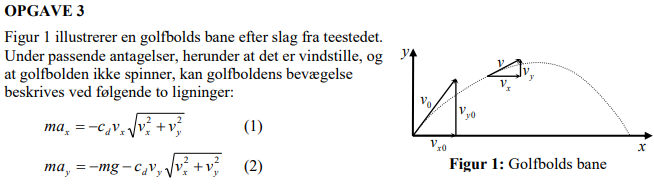

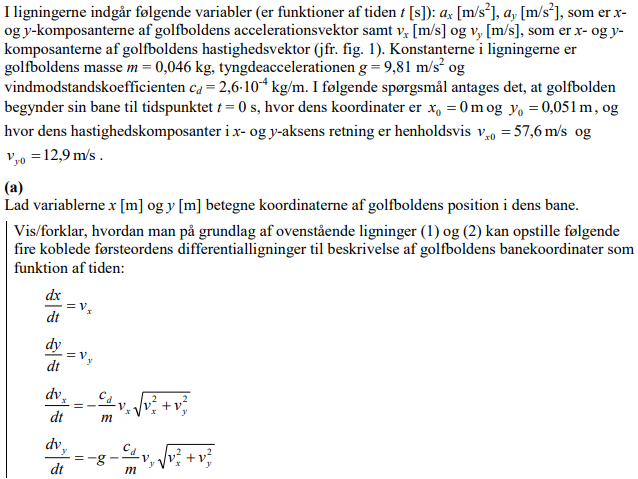

Den differentierede stedfunktion bliver til hastigheden $\frac{dx}{dt}=v_x$ her i x retning. Det sammed gælder for y retning hvis der v integres over en tid får vi strækningen vi er flyttede os.

for $\frac{dv_x}{dt}$ kan vi dividere med massen m og vi får således ligning (1)

for $\frac{dv_y}{dt}$ gøres det samme for at få ligning (2).

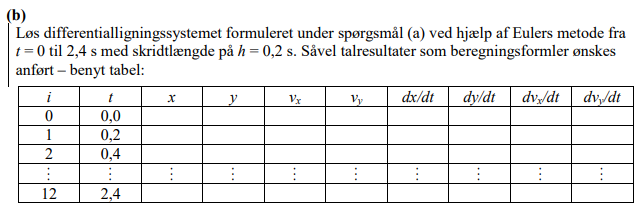

clear
m = 0.046

m = 0.0460

g = 9.81

g = 9.8100

c_d = 2.6 * 10^-4

c_d = 2.6000e-04


t_0 = 0;
t_f = 2.4;
h = 0.2;
ts = [t_0,t_f];

v_x0 = 57.6;
v_y0 = 12.9;


x_0 = 0;
y_0 = 0.051;
X0 = [x_0, v_x0]

X0 =          0   57.6000


Y0 = [y_0, v_y0]

Y0 =     0.0510   12.9000



% syms v_x v_y

% dxdt = v_x
% dydt = v_y
% dYdt1 = [dvxdt, dvydt]
% eulsys(dYdt1,ts,Y01,h)
dXdt = @(t,X,Y) [X(2), -c_d/m * X(2) * sqrt(X(2)^2 + Y(2)^2)] % Definerer dYdt - udregner IKKE noget!

dXdt = function_handle with value:
    @(t,X,Y)[X(2),-c_d/m*X(2)*sqrt(X(2)^2+Y(2)^2)]


% dvxdt =-c_d/m * v_x * sqrt(v_x^2 + v_y^2)
% dvydt = -g - c_d/m * v_y * sqrt(v_x^2 + v_y^2)
dYdt = @(t,X,Y) [Y(2), -g - c_d/m * Y(2) * sqrt(X(2)^2 + Y(2)^2)]

dYdt = function_handle with value:
    @(t,X,Y)[Y(2),-g-c_d/m*Y(2)*sqrt(X(2)^2+Y(2)^2)]




% g = 9.81; m = 68.1; cd = 0.25;
% dYdt = @(t,Y) [Y(2), g-cd/m*Y(2)^2]; % Definerer dYdt - udregner IKKE noget!
% Y0 = [0 0];
% tidsinterval = [0 12];
% h = 2;

[t,Y,X] = Egen_eulsys(dYdt,dXdt,ts,Y0,X0,h);

Not enough input arguments.

Error in Aflevering_5 (line 26)
dXdt = @(t,X,Y) [X(2), -c_d/m * X(2) * sqrt(X(2)^2 + Y(2)^2)] % Definerer dYdt - udregner IKKE noget!

Error in Egen_eulsys (line 29)
  X(i+1,:) = X(i,:) + dXdt(t(i),X(i,:))*h;


% disp('================ Eulers metode =================')
% [t,X] = eulsys(dXdt,ts,X0,h);
% [t,Y] = eulsys(dYdt,ts,Y0,h);
% x = Y(:,1); v = Y(:,2);
% disp(table(t,x,v))
% figure(1), plot(t,x,'-o'), hold on
% xlabel('t (s)'), ylabel('x (m)')
% figure(2), plot(t,v,'-o'), hold on
% xlabel('t (s)'), ylabel('v (m/s)')

%Vi bruger euler metoden i funktionen
% eulsys(dYdt,ts,Y0,h)



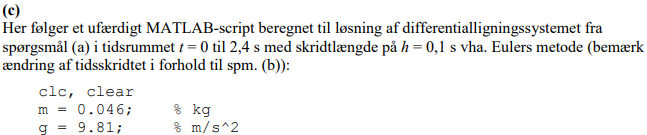

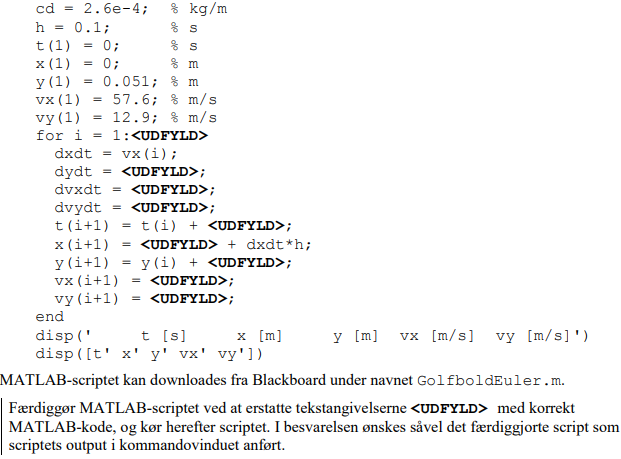

cd = 2.6e-4; % kg/m
h = 0.1; % s
t(1) = 0; % s
x(1) = 0; % m
y(1) = 0.051; % m
vx(1) = 57.6; % m/s
vy(1) = 12.9; % m/s
for i = 1:24; %<UDFYLD>
 dxdt = vx(i);
 dydt = vy(i);%<UDFYLD>;
 dvxdt = -c_d/m * vx(1) * sqrt(vx(1)^2 + vy(1)^2); %<UDFYLD>;
 dvydt = -g - c_d/m * vy(1) * sqrt(vx(1)^2 + vy(1)^2); %<UDFYLD>;
 t(i+1) = t(i) + h;%<UDFYLD>;
 x(i+1) = x(i) + dxdt*h; %X(i,:) + dXdt(t(i),X(i,:))*h;
 y(i+1) = y(i) + dydt*h;
 vx(i+1) = vx(i) + dvxdt*h;
 vy(i+1) = vy(i) + dvydt*h;
end
disp(' t [s] x [m] y [m] vx [m/s] vy [m/s]')

 t [s] x [m] y [m] vx [m/s] vy [m/s]


disp([t' x' y' vx' vy'])

         0         0    0.0510   57.6000   12.9000
    0.1000    5.7600    1.3410   55.6783   11.4886
    0.2000   11.3278    2.4899   53.7566   10.0772
    0.3000   16.7035    3.4976   51.8349    8.6659
    0.4000   21.8870    4.3642   49.9132    7.2545
    0.5000   26.8783    5.0896   47.9915    5.8431
    0.6000   31.6774    5.6739   46.0697    4.4317
    0.7000   36.2844    6.1171   44.1480    3.0203
    0.8000   40.6992    6.4191   42.2263    1.6089
    0.9000   44.9218    6.5800   40.3046    0.1976
    1.0000   48.9523    6.5998   38.3829   -1.2138
    1.1000   52.7906    6.4784   36.4612   -2.6252
    1.2000   56.4367    6.2159   34.5395   -4.0366
    1.3000   59.8907    5.8122   32.6178   -5.4480
    1.4000   63.1524    5.2674   30.6961   -6.8594
    1.5000   66.2221    4.5815   28.7744   -8.2707
    1.6000   69.0995    3.7544   26.8527   -9.6821
    1.7000   71.7848    2.7862   24.9309  -11.0935
    1.8000   74.2778    1.6768   23.0092  -12.5049
    1.9000   76.5788    0.4264 

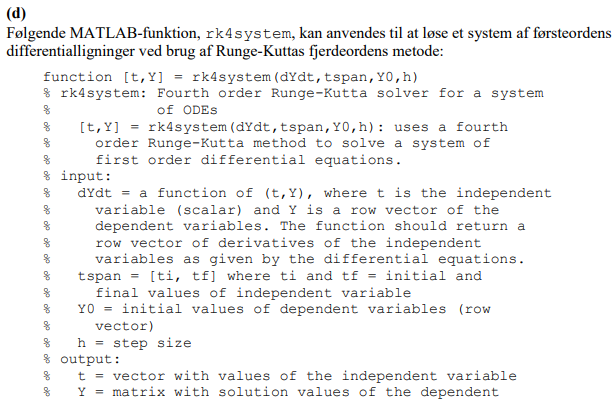

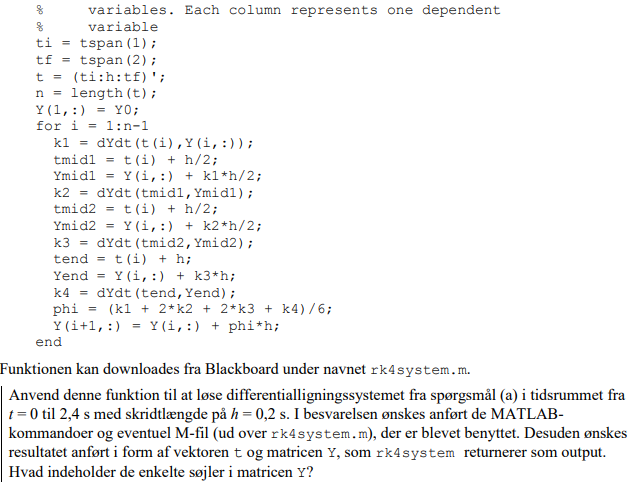

# Eksamens sæt F16